Exercises on Noncooperative game theory

a) Find strictly dominated strategies (if any) and reduce the cost matrix accordingly.

b) Do pure strategies Nash equilibria exist?

c) Find all the mixed strategies Nash equilibria of the game by solving the related linear program-

ming problems.

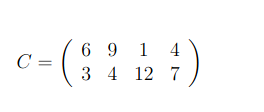

close all;
clear;
clc;


C = [6 9 1 4 
     3 4 12 7]

C =      6     9     1     4
     3     4    12     7



Cr = [9 1 4
      4 12 7]

Cr =      9     1     4
     4    12     7



[m, n] = size(C);


% No Nash equilibrium

% Linear programming

f = [zeros(m,1)
     1];

A = [C' -ones(n,1)];
b = [zeros(n,1)];

Aeq = [ones(m,1)' 0];

beq = 1;

lb = [zeros(m,1) 
      -inf];

up = [];

options = optimset('Display', 'off');
[sol,Val,exitflag,output,lambda] = linprog(f,A,b,Aeq,beq,lb,up,options)

sol =     0.5000
    0.5000
    6.5000


Val = 6.5000

exitflag = 1

output = struct with fields:
         iterations: 4
    constrviolation: 0
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 8.8818e-16


lambda = struct with fields:
      lower: [3×1 double]
      upper: [3×1 double]
      eqlin: -6.5000
    ineqlin: [4×1 double]


x = sol(1:m)

x =     0.5000
    0.5000


y = lambda.ineqlin

y =          0
    0.6875
    0.3125
         0


% Player 1

No Dominated Strategies

% Player 2

Strategy 1 is dominated by Strategy 2 

% Solve The linear programming

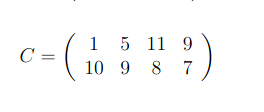

close all;
clear;
clc;

C = [1 5 11 9 
     10 9 8 7]

C =      1     5    11     9
    10     9     8     7



Cr = [1 5 11
      10 9 8]

Cr =      1     5    11
    10     9     8



[m,n] = size(C);

f = [zeros(m,1)
     1];

A = [C' -ones(n,1)];
b = [zeros(n,1)]'

b =      0     0     0     0



Aeq = [ones(m,1)' 0];
beq = 1;

lb = [zeros(m,1)
     -inf];

up = [];

options = optimset('Display', 'off');

[sol,value, flag, output, lambda] = linprog(f,A,b,Aeq,beq,lb,up,options);

x = sol(1:m)

x =     0.1667
    0.8333


y = lambda.ineqlin

y =     0.2500
         0
    0.7500
         0



% No Nash Equilibrium

% Player 1

% Player 2

Strategy 4 is dominated by Strategy 3

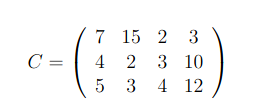

close all;
clear;
clc;

C = [7 15 2 3
     4 2 3 10
     5 3 4 12]

C =      7    15     2     3
     4     2     3    10
     5     3     4    12



Cr = [7 15   3
      4  2  10
      5  3  12]

Cr =      7    15     3
     4     2    10
     5     3    12



[m,n] = size(C);

f = [zeros(m,1)
     1];

A = [C' -ones(n,1)];
b = [zeros(n,1)];

Aeq = [ones(m, 1)' 0];
beq = 1;

lb = [zeros(m,1) 
      -inf];
up = [];

options = optimset('Display', 'off');
[sol, value, flag, output, lambda] = linprog(f,A,b,Aeq,beq,lb,up,options);

x = sol(1:m)

x =     0.4000
    0.6000
         0


y = lambda.ineqlin     

y =          0
    0.3500
         0
    0.6500



% No Nash Equilibrium

% Player 1

No dominated Strategy. Strategy 3, x3 = 0. 

% Player 2

Strategy 3 is dominated by Strategy 4. Strategy 1, y1 = 0. Strategy 3, y3 = 0. 

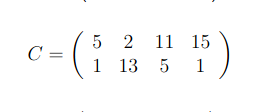     

close all;
clear;
clc;

C = [5 2 11 15
     1 13 5 1]

C =      5     2    11    15
     1    13     5     1



[m,n] = size(C);


f = [zeros(m,1)
     1];

A = [C' -ones(n,1)];
b = [zeros(n,1)];

Aeq = [ones(m,1)' 0];
beq = 1;

lb = [zeros(m,1) 
      -inf];

up = [];

options = optimset('Display', 'off');
[sol, value, flag, output, lambda] = linprog(f,A,b,Aeq,beq,lb,up,options)

sol =     0.4706
    0.5294
    7.8235


value = 7.8235

flag = 1

output = struct with fields:
         iterations: 4
    constrviolation: 8.8818e-16
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 8.8818e-16


lambda = struct with fields:
      lower: [3×1 double]
      upper: [3×1 double]
      eqlin: -7.8235
    ineqlin: [4×1 double]



x = sol(1:m)

x =     0.4706
    0.5294


y = lambda.ineqlin

y =          0
    0.3529
    0.6471
         0



% No Nash Equilibrium
% No Strictrly dominance

% Player 2 y1 = 0 and y3 =0


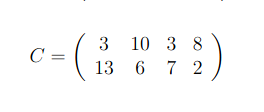

close all;
clear;
clc;

C = [3 10 3 8
     13 6 7 2]

C =      3    10     3     8
    13     6     7     2



Cr = [ 3 10 3
      10  6 7]

Cr =      3    10     3
    10     6     7



[m,n] = size(C);

f = [zeros(m,1) 
     1];

A = [C' -ones(n,1)];
b = [zeros(n,1)];

Aeq = [ones(m,1)' 0];
beq = 1;

lb = [zeros(m,1)
      -inf];
up = [];

options = optimset('Display', 'off');

[sol, value, flag, output, lambda] = linprog(f,A,b,Aeq,beq,lb,up,options);

x = sol(1:m)

x =     0.5000
    0.5000


y = lambda.ineqlin

y =     0.2857
    0.7143
         0
         0


% No Nash Equilibrium
% Player 1 No dominated strategy

% Player 2

Strategy 4 is dominated by Strategy 2

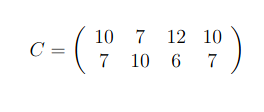

close all;
clear;
clc;

C = [10 7  12 10
     7  10 6  7]

C =     10     7    12    10
     7    10     6     7



[m,n] = size(C);
f = [zeros(m,1)
     1];

A = [C' -ones(n,1)];
b = [zeros(n,1)];

Aeq = [ones(m,1)' 0];
beq = 1;

lb = [zeros(m,1)
     -inf];

up = [];

options = optimset('Display', 'off');
[sol, value, flag, output, lambda] = linprog(f,A,b,Aeq, beq, lb, up, options)

sol =     0.4444
    0.5556
    8.6667


value = 8.6667

flag = 1

output = struct with fields:
         iterations: 3
    constrviolation: 2.2204e-16
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 1.7764e-15


lambda = struct with fields:
      lower: [3×1 double]
      upper: [3×1 double]
      eqlin: -8.6667
    ineqlin: [4×1 double]


x = sol(1:m)

x =     0.4444
    0.5556


y = lambda.ineqlin

y =          0
    0.6667
    0.3333
         0



% No Nash equilibrium 
% No dominated strategies
